clear; close all; clc;

conditions = zeros(4,1);
conditions(1,1) = 100;
conditions(2,1) = 0;
conditions(3,1) = 50;
conditions(4,1) = 0

conditions =    100
     0
    50
     0



A = [0,1,0,0;-(4.66+4.66)/0.0917,0,4.66/0.0917,0;0,0,0,1;4.66/0.0765,0,-4.66/0.0765,0]

A =          0    1.0000         0         0
 -101.6358         0   50.8179         0
         0         0         0    1.0000
   60.9150         0  -60.9150         0


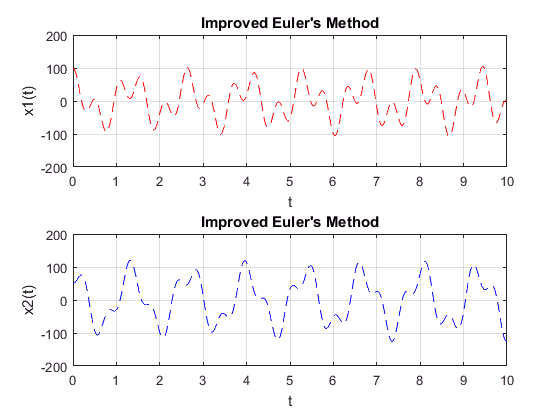



N1 = 500;
N2 = 50;
N3 = 100;

T = 10;

[x_iem_1, x2_iem_1, t_iem_1] = IEMSolver(A,conditions,T,N1);
[x_iem_2, t_iem_2] = IEMSolver(A,conditions,T,N2);
[x_iem_3, t_iem_3] = IEMSolver(A,conditions,T,N3);

%Plot IEM Solutions
t_exact = 0:0.01:T;
figure
%Plot x(t) vs t
subplot(2,1,1)
plot(t_iem_1, x_iem_1, '--r')
hold on


%Annotations
ylabel('x1(t)')
xlabel('t')
title('Improved Euler''s Method')
grid on

%Plot x2(t) vs t
subplot(2,1,2)
plot(t_iem_1, x2_iem_1, '--b')
hold on

%Annotations
ylabel('x2(t)')
xlabel('t')
title('Improved Euler''s Method')
grid on

function [x1, x2, t] = IEMSolver(A,conditions,T,N)
%Improved Euler method integration for IVPs

 dt = T/N;
 t = 0:dt:T;
 SOL = NaN(4,length(t));

 SOL(1,1) = conditions(1,1);
 SOL(2,1) = conditions(2,1);
 SOL(3,1) = conditions(3,1);
 SOL(4,1) = conditions(4,1);
 
for k = 2:length(t)
 %EM Solution (temporary variable) 
 EM = SOL(:,k-1) + dt*A*SOL(:,k-1);
 %IEM Solution
 SOL(:,k) = SOL(:,k-1) + dt/2*(A*SOL(:,k-1) + A*EM);
 
end
 x1 = SOL(1,:);
 x2 = SOL(3,:);

end